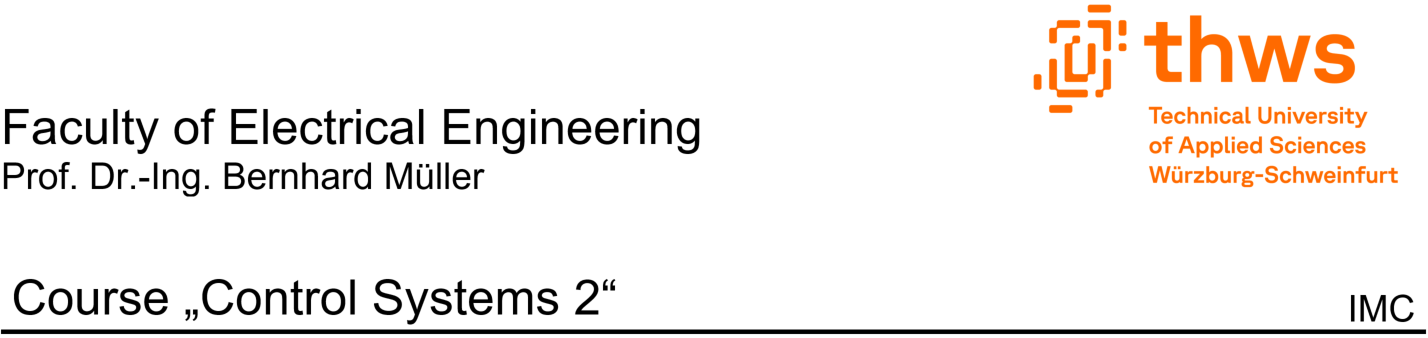

# **Mathematical Modelling and State Equations of "Ball-on-Beam" System**

In this document a mathematical model of the "ball-on-beam" system illustrated below is derived and expressed in form of nonlinear state equations. To this end, Lagrange's approach for modelling mechanical systems is applied.

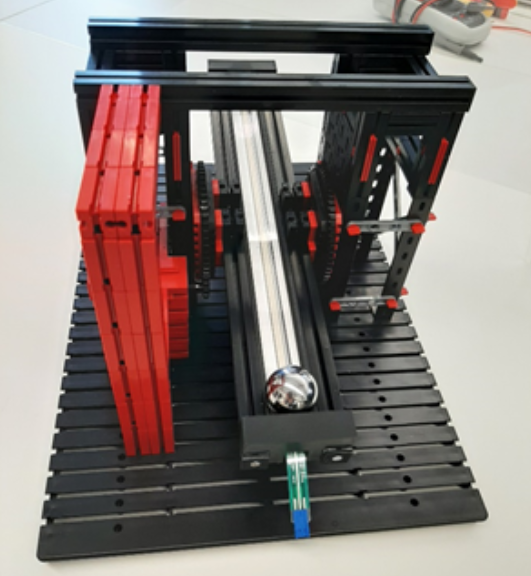  

## Definitions and Variable Declarations

clc;                                    % clear display
clearvars;                              % reset variables

#### System description and definition of important quantities

The following schematic diagram defines coordinate systems and counting directions of important quantities. 

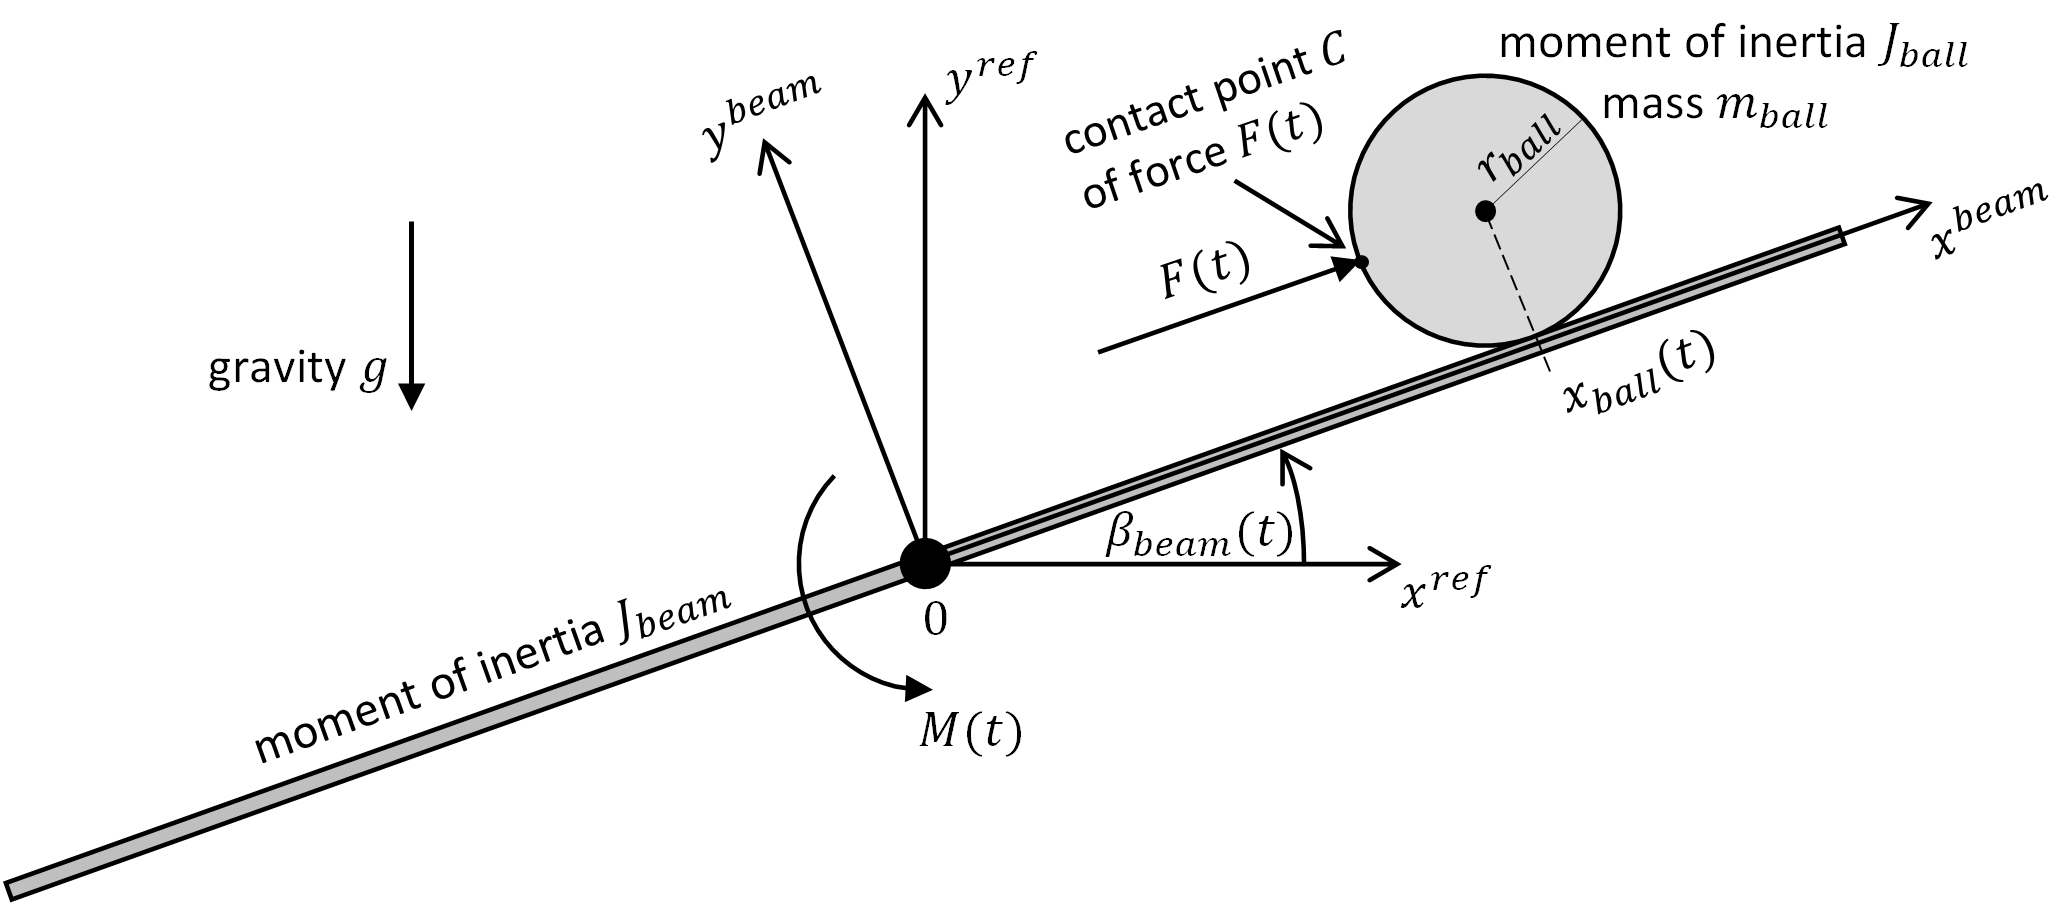

In particular, the figure introduces the fixed Cartesian reference frame $\left(x^{\textrm{ref}} ,y^{\textrm{ref}} \right)$ and the beam-fixed coordinate system $\left(x^{\textrm{beam}} ,y^{\textrm{beam}} \right)$ which is rotated by the beam angle $\beta_{\textrm{beam}} \left(t\right)$ with respect to the reference frame. The beam is pivot-mounted at the common origin of these coordinate systems such that it can freely rotate around the $z$-axis. By means of an electric motor, which is of no further interest, the torque $M\left(t\right)$ can be applied to the beam, i.e. $M\left(t\right)$ represents the control input $u\left(t\right)$. A force $F\left(t\right)$ acting on the ball must be taken into account as disturbance input $z\left(t\right)$. It is assumed that the ball rolls on the beam without slipping at all times. All other friction forces and/or torques are neglected. The measured variables are the beam angle $\beta_{\textrm{beam}} \left(t\right)$ and the ball position on the beam $x_{\textrm{ball}} \left(t\right)$, which corresponds to the $x$-value of the ball's center of mass in beam-coordinates. The meaning of some other parameters and quantities of interest is described by the comments in the following variable declaration.

#### **Declare symbolic variables**

syms x_ball(t)                          % ball position on beam (in beam coordinate system)
syms beta_beam(t)                       % beam angle
syms M(t)                               % motor torque acting on beam
syms F(t)                               % disturbance force acting on ball
syms r_Ball                             % radius of ball
syms J_Ball                             % moment of inertia of ball with respect to its symmetry axis
syms m_Ball                             % mass of ball
syms G                                  % gravity of earth
syms J_Beam                             % moment of inertia of beam with respect to its fixed axis of rotation arount pivot point
syms q1(t) q2(t)                        % generalized coordinates   
syms x1(t) x2(t) x3(t) x4(t) u(t) z(t)  % state variables x, control input u, disturbance input z
syms x1dot x2dot x3dot x4dot            % auxiliary variables needed to express the state differential equations

## **Specify Generalized Coordinates**

It is obvious that the position and orientation of the ball and the beam are completely defined if both $x_{\textrm{ball}}$ and $\beta {\;}_{\textrm{beam}}$ are known. Thus, the system has two degrees of freedom and the two measured variables can be defined as generalized coordinates:

x_ball = q1

$$x\_ball(t) = q_{1}\left(t\right)$$

beta_beam = q2

$$beta\_beam(t) = q_{2}\left(t\right)$$

## **Determine Total Kinetic Energy of the System**

The "ball-on-beam" system consists of two rigid bodies: the ball and the beam. Consequently, the total kinetic energy can be expressed as the sum of the kinetic energy of the ball and the kinetic energy of the beam.

### **Kinetic energy of the ball**

The overall motion of the ball is rather complex, since it simultaneously performs a rotational and a translational movement. With respect to its center of mass, however, the kinetic energy of any rigid body can still be stated as a simple sum of a purely translational and a purely rotational movement in relation to a fixed and non-moving reference coordinate system. Thus, the total kinetic energy of the ball $T_{\textrm{ball}}$ can be calculated as


$$T_{\textrm{ball}} =\frac{1}{2}J_{\textrm{ball}} {\left|\omega {\;}_{\textrm{ball}\;}^{\textrm{ref}} \right|}^2 +\frac{1}{2}m_{\textrm{ball}} {\left|v_{\textrm{ball}}^{\textrm{ref}} \right|}^2$$


with

$\left|\omega {\;}_{\textrm{ball}\;}^{\textrm{ref}} \right|$: absolute value of angular ball speed around its center of mass with respect to fixed reference coordinate system

$\left|v_{\textrm{ball}}^{\textrm{ref}} \right|$: absolute value of translational speed at center of mass with respect to fixed reference coordinate system

#### Calculation of the translational speed at the center of mass $\left|v_{\textrm{ball}}^{\textrm{ref}} \right|$

Position of the ball's center of mass in the fixed Cartesian reference frame as a function of the generalized coordinates:

xref_ball(t) =x_ball(t)*cos(beta_beam(t)) - r_Ball*sin(beta_beam(t))

$$xref\_ball(t) = \cos\left(q_{2}\left(t\right)\right)\,q_{1}\left(t\right)-r_{\mathrm{Ball}}\,\sin\left(q_{2}\left(t\right)\right)$$

yref_ball(t) =x_ball(t) * sin(beta_beam(t)) + r_Ball * cos(beta_beam(t))

$$yref\_ball(t) = r_{\mathrm{Ball}}\,\cos\left(q_{2}\left(t\right)\right)+\sin\left(q_{2}\left(t\right)\right)\,q_{1}\left(t\right)$$

Absolute value of translational ball speed as a function of $q_{1/2}$ and ${\dot{q} }_{1/2}$ with respect to the fixed reference coordinate system:

vref_ball(t) = simplify(sqrt(diff(xref_ball(t),t)^2+diff(yref_ball(t),t)^2))

$$vref\_ball(t) = \sqrt{{r_{\mathrm{Ball}}}^{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+{q_{1}\left(t\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}-2\,r_{\mathrm{Ball}}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}$$

#### Calculation of the angular speed around the center of mass $\omega {\;}_{\textrm{ball}\;}^{\textrm{ref}}$

Applying the summation rule for angular velocities (see e.g. [1]), the total angular speed of the ball $\underline{\omega} {\;}_{\textrm{ball}\;}^{\textrm{ref}}$ can be stated as the sum of the angular speed of the ball with respect to the beam $\underline{\omega} {\;}_{\textrm{ball}\;}^{\textrm{beam}}$ and the angular speed of the beam with respect to the fixed reference coordinate sytem $\underline{\omega} {\;}_{\textrm{beam}\;}^{\textrm{ref}}$, i.e. $\underline{\omega} {\;}_{\textrm{ball}\;}^{\textrm{ref}} =\underline{\omega} {\;}_{\textrm{ball}\;}^{\textrm{beam}} +\underline{\omega} {\;}_{\textrm{beam}\;}^{\textrm{ref}}$. Since in case of the "ball-on-beam" system all angular speed vectors are parallel to the $z$-axis, this vector equation can be simplified to the scalar relationship $\omega {\;}_{\textrm{ball}\;}^{\textrm{ref}} =\omega {\;}_{\textrm{ball}\;}^{\textrm{beam}} +\omega {\;}_{\textrm{beam}\;}^{\textrm{ref}}$ where

omegaref_beam(t) = diff(q2(t),t)

$$omegaref\_beam(t) = \frac{\partial }{\partial t}q_{2}\left(t\right)$$

and $\underline{\omega} {\;}_{\textrm{ball}\;}^{\textrm{beam}}$ follows from the ideal rolling conditions as

omegabeam_ball(t) = -diff(x_ball,t)/r_Ball

$$omegabeam\_ball(t) = -\frac{\frac{\partial }{\partial t}q_{1}\left(t\right)}{r_{\mathrm{Ball}}}$$

Note that there is a negative sign in the later equation. It is caused by the fact that a negative rotation of the ball against the "right-hand-rule" is needed to move the system into positive $x^{\textrm{beam}}$ direction (see definition of coordinate systems and counting direction in the figure above).

Summing both terms up yields

omegaref_ball(t) = omegaref_beam(t) + omegabeam_ball(t)

$$omegaref\_ball(t) = \frac{\partial }{\partial t}q_{2}\left(t\right)-\frac{\frac{\partial }{\partial t}q_{1}\left(t\right)}{r_{\mathrm{Ball}}}$$

#### Calculation of the kinetic energy of the ball $T_{\textrm{ball}}$

Using the above formula for the kinetic energy expressed with respect to the mass center point finally yields

T_ball(t) = simplify(1/2*m_Ball*vref_ball(t)^2+1/2*J_Ball*omegaref_ball(t)^2)

$$T\_ball(t) = \frac{J_{\mathrm{Ball}}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)-\frac{\frac{\partial }{\partial t}q_{1}\left(t\right)}{r_{\mathrm{Ball}}}\right)}^{2}}{2}+\frac{m_{\mathrm{Ball}}\,\left({\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+{r_{\mathrm{Ball}}}^{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}+{q_{1}\left(t\right)}^{2}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}-2\,r_{\mathrm{Ball}}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}$$

### Kinetic energy of the beam

The beam performs a purely rotational movement around the fixed axis of rotation at the center of the coordinate system (see figure above). Thus, using $J_{\textrm{beam}}$ as the moment of inertia of the beam with respect to that axis, the total kinetic energy of the beam is

T_beam(t) = 1/2*J_Beam*omegaref_beam^2

$$T\_beam(t) = \frac{J_{\mathrm{Beam}}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}}{2}$$

### **Total kinetic energy of the system**

The total kinetic energy of the system results from the sum of the kinetic energy of the ball and of the beam as

T(t) = T_ball(t) + T_beam(t)

$$T(t) = \begin{array}{l} \frac{J_{\mathrm{Ball}}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)-\frac{\frac{\partial }{\partial t}q_{1}\left(t\right)}{r_{\mathrm{Ball}}}\right)}^{2}}{2}+\frac{m_{\mathrm{Ball}}\,\left({\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+{r_{\mathrm{Ball}}}^{2}\,\sigma_{1}+{q_{1}\left(t\right)}^{2}\,\sigma_{1}-2\,r_{\mathrm{Ball}}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}+\frac{J_{\mathrm{Beam}}\,\sigma_{1}}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2} \end{array}$$

## **Determine Total Potential Energy of the System**

The impact of gravity can be expressed using a potential energy term. As the beam's center of mass does not move, however, the total potential energy of the system is solely determined by the ball, i.e. $V=V_{\textrm{ball}}$. Moreover, the ball's potential energy $V_{\textrm{ball}}$only depends on its $y$-coordinate in the fixed Cartesian reference coordinate system. Assuming without loss of generality that ${V=V}_{\textrm{ball}} =0$ would hold if the ball's center of mass was at the origin of the coordinate system, $V$ can be expressed as

V(t) = G*m_Ball*yref_ball(t)

$$V(t) = G\,m_{\mathrm{Ball}}\,\left(r_{\mathrm{Ball}}\,\cos\left(q_{2}\left(t\right)\right)+\sin\left(q_{2}\left(t\right)\right)\,q_{1}\left(t\right)\right)$$

## Lagrangian 

The Lagrangian 


$$L=T-V$$


can now easily be stated as a function of $q_{1/2}$ and ${\dot{q} }_{1/2}$:

L(t) = simplify(T(t) - V(t))

$$L(t) = \begin{array}{l} \frac{J_{\mathrm{Ball}}\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)-\frac{\frac{\partial }{\partial t}q_{1}\left(t\right)}{r_{\mathrm{Ball}}}\right)}^{2}}{2}+\frac{m_{\mathrm{Ball}}\,\left({\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}+{r_{\mathrm{Ball}}}^{2}\,\sigma_{1}+{q_{1}\left(t\right)}^{2}\,\sigma_{1}-2\,r_{\mathrm{Ball}}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}{2}+\frac{J_{\mathrm{Beam}}\,\sigma_{1}}{2}-G\,m_{\mathrm{Ball}}\,\left(r_{\mathrm{Ball}}\,\cos\left(q_{2}\left(t\right)\right)+\sin\left(q_{2}\left(t\right)\right)\,q_{1}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2} \end{array}$$

## **Non-conservative Generalized Forces**

In general, the non-conservative generalized forces $Q_{i,\textrm{nc}}$ of a system with $N$ degrees of freedom are given as [1]

$Q_{i,\textrm{nc}} =\left(\sum_{k=1}^K {\underline{F} }_{k,\textrm{nc}}^T \frac{\partial {\underline{v} }_{k\;} }{\partial {\dot{q} }_i }\right)+\left(\sum_{l=1}^L {\underline{M} }_{l,\textrm{nc}}^T \frac{\partial {\underline{\omega} }_{l\;} }{\partial {\dot{q} }_i }\right)$, $i=1,2,\ldotp \ldotp \ldotp ,N$

where ${\underline{F} }_{k,\textrm{nc}}$, $k=1,2,\ldotp \ldotp \ldotp ,K$, and ${\underline{M} }_{l,\textrm{nc}}$, $l=1,2,\ldotp \ldotp \ldotp ,L$, represent all non-constraint and non-conservative force and torque vectors acting on the system and ${\underline{v} }_{k\;}$, $k=1,2,\ldotp \ldotp \ldotp ,K$, as well as ${\underline{\omega} }_{l\;}$, $l=1,2,\ldotp \ldotp \ldotp ,L$, are the speed and angular speed vectors of the corresponding contact points. 

Applied to the "ball-and-beam" system, the number of degrees of freedom is $N=2$ and the external force $F\left(t\right)$ as well as the motor torque $M\left(t\right)$ (see figure above) represent the only non-conservative quantities acting on the mechanics. Thus, expressed in reference coordinates the formula above simplifies to the two non-conservative generalized force terms


$$\begin{array}{l}
Q_{1,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_1 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{beam}}^{\textrm{ref}} \;}{\partial \dot{q_1 } }\\
Q_{2,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_2 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{beam}}^{\textrm{ref}} \;}{\partial \dot{q_2 } }
\end{array}$$


#### Force vector ${\underline{F} }^{\textrm{ref}\;}$ and corresponding speed vector of the contact point ${\underline{v} }_C^{\textrm{ref}}$ in reference coordinates

In beam coordinates the force $F\left(t\right)$ acts in positive $x$-direction. Consequently, with respect to the fixed reference coordinate system, the force vector can be expressed as

Fref_vec(t) = F(t)*[cos(q2);sin(q2);0]

$$Fref\_vec(t) = \left(\begin{array}{c} \cos\left(q_{2}\left(t\right)\right)\,F\left(t\right)\\ \sin\left(q_{2}\left(t\right)\right)\,F\left(t\right)\\ 0 \end{array}\right)$$

The position of the corresponding contact point $C$ (see figure) of the force $F\left(t\right)$ in beam coordinates is  

xbeam_C(t) = x_ball(t)-r_Ball

$$xbeam\_C(t) = q_{1}\left(t\right)-r_{\mathrm{Ball}}$$

ybeam_C = r_Ball 

$$ybeam\_C = r_{\mathrm{Ball}}$$

Transformed into the fixed Cartesian reference frame, the contact point $C$ is described by

xref_C(t) = xbeam_C(t)*cos(beta_beam(t))-r_Ball*sin(beta_beam(t))

$$xref\_C(t) = -r_{\mathrm{Ball}}\,\sin\left(q_{2}\left(t\right)\right)-\cos\left(q_{2}\left(t\right)\right)\,\left(r_{\mathrm{Ball}}-q_{1}\left(t\right)\right)$$

yref_C(t) = xbeam_C(t)*sin(beta_beam(t))+r_Ball*cos(beta_beam(t))

$$yref\_C(t) = r_{\mathrm{Ball}}\,\cos\left(q_{2}\left(t\right)\right)-\sin\left(q_{2}\left(t\right)\right)\,\left(r_{\mathrm{Ball}}-q_{1}\left(t\right)\right)$$

Calculating the time derivative yields the speed vector ${\underline{v} }_C$ of the contact point $C$ in reference coordinates:

vref_Cvec(t)=[simplify(diff(xref_C(t),t));simplify(diff(yref_C(t),t));0]

$$vref\_Cvec(t) = \left(\begin{array}{c} \cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+\sin\left(q_{2}\left(t\right)\right)\,\left(r_{\mathrm{Ball}}-q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-r_{\mathrm{Ball}}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)-\cos\left(q_{2}\left(t\right)\right)\,\left(r_{\mathrm{Ball}}-q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-r_{\mathrm{Ball}}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ 0 \end{array}\right)$$

#### Torque vector ${\underline{M} }^{\textrm{ref}\;}$ and corresponding angular speed vector ${\underline{\omega} }_{\textrm{beam}}^{\textrm{ref}} \;$ in reference coordinates

The motor torque $M\left(t\right)$acts around the $z$-axis which represents the fixed axis of rotation for the beam. Thus, we can state the associated torque vector according to

Mref_vec(t) = M(t)*[0;0;1]

$$Mref\_vec(t) = \left(\begin{array}{c} 0\\ 0\\ M\left(t\right) \end{array}\right)$$

and the corresponding angular speed vector as

omegaref_beamvec(t) = omegaref_beam(t)*[0;0;1]

$$omegaref\_beamvec(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

with respect to the Cartesian reference frame and considering the counting directions specified in the figure above.

#### Non-conservative generalized force $Q_{1,\textrm{nc}}$ associated to $q_1$

Evaluating


$$Q_{1,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_1 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{beam}}^{\textrm{ref}} \;}{\partial \dot{q_1 } }$$


results in

Q1_nc(t) = simplify(transpose(Fref_vec(t))*(diff(vref_Cvec(t),diff(q1(t),t)))+transpose(Mref_vec(t))*(diff(omegaref_beamvec(t),diff(q1(t),t))))

$$Q1\_nc(t) = F\left(t\right)$$

####  Non-conservative generalized force $Q_{2,\textrm{nc}}$ associated to $q_2$

Evaluating


$$Q_{2,\textrm{nc}} ={\left({\underline{F} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{v} }_C^{\textrm{ref}} }{\partial \dot{q_2 } \;\;}+{\left({\underline{M} }^{\textrm{ref}} \right)}^T \frac{\;\partial {\underline{\omega} }_{\textrm{beam}}^{\textrm{ref}} \;}{\partial \dot{q_2 } }$$


results in

Q2_nc(t) = simplify(transpose(Fref_vec(t))*(diff(vref_Cvec(t),diff(q2(t),t)))+transpose(Mref_vec(t))*(diff(omegaref_beamvec(t),diff(q2(t),t))))

$$Q2\_nc(t) = M\left(t\right)-r_{\mathrm{Ball}}\,F\left(t\right)$$

## Equations of Motion in Generalized Coordinates

In general, using the Lagrangian $L$ and the non-conservative generalized forces $Q_{i,\textrm{nc}}$, the equations of motion in the generalized coordinates are obtained from the $N$ Lagrange's equations (of 2nd kind)

$\frac{d\;}{\textrm{dt}}\left(\frac{\partial L\;}{\partial {\dot{q} }_i }\right)-\frac{\;\partial L}{\partial q_{i\;} }=Q_{i,\textrm{nc}}$ ,  $i=1,2,\ldotp \ldotp \ldotp ,N$

Applied to the "ball-on-beam" system with two degrees of freedom ($N=2$), the evaluation of


$$\begin{array}{l}
\frac{d\;}{\textrm{dt}}\left(\frac{\partial L\;}{\partial {\dot{q} }_1 }\right)-\frac{\;\partial L}{\partial q_{1\;} }=Q_{1,\textrm{nc}} \\
\frac{d\;}{\textrm{dt}}\left(\frac{\partial L\;}{\partial {\dot{q} }_2 }\right)-\frac{\;\partial L}{\partial q_{2\;} }=Q_{2,\textrm{nc}} 
\end{array}$$


results in the following two differential equations in the generalized coordinates:

deq1 = simplify(diff(diff(L(t),diff(q1(t),t)),t) - diff(L(t),q1(t))) == Q1_nc(t)

$$deq1 = G\,m_{\mathrm{Ball}}\,\sin\left(q_{2}\left(t\right)\right)-\frac{m_{\mathrm{Ball}}\,\left(2\,r_{\mathrm{Ball}}\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)-2\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\right)}{2}+\frac{J_{\mathrm{Ball}}\,\left(\frac{\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)}{r_{\mathrm{Ball}}}-\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\right)}{r_{\mathrm{Ball}}}-m_{\mathrm{Ball}}\,q_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}=F\left(t\right)$$

deq2 = simplify(diff(diff(L(t),diff(q2(t),t)),t) - diff(L(t),q2(t))) == Q2_nc(t)

$$deq2 = \begin{array}{l} J_{\mathrm{Beam}}\,\sigma_{1}+J_{\mathrm{Ball}}\,\sigma_{1}+m_{\mathrm{Ball}}\,{q_{1}\left(t\right)}^{2}\,\sigma_{1}-m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,\sigma_{2}-\frac{J_{\mathrm{Ball}}\,\sigma_{2}}{r_{\mathrm{Ball}}}+m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}\,\sigma_{1}+2\,m_{\mathrm{Ball}}\,q_{1}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+G\,m_{\mathrm{Ball}}\,\cos\left(q_{2}\left(t\right)\right)\,q_{1}\left(t\right)-G\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,\sin\left(q_{2}\left(t\right)\right)=M\left(t\right)-r_{\mathrm{Ball}}\,F\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}$$

## Derive (Nonlinear) State Equations

#### Define state variables

In order to obtain a state space description of the "ball-on-beam" system from the equations of motion, the generalized coordinates and their first-order time derivatives are introduced as state variables:

x1_def = q1(t) == x1(t)              % x1 --> ball position on beam

$$x1\_def = q_{1}\left(t\right)=x_{1}\left(t\right)$$

x2_def = diff(q1(t),t) == x2(t)      % x2 --> translational ball speed relative to beam

$$x2\_def = \frac{\partial }{\partial t}q_{1}\left(t\right)=x_{2}\left(t\right)$$

x3_def = q2(t) == x3(t)              % x3 --> beam angle

$$x3\_def = q_{2}\left(t\right)=x_{3}\left(t\right)$$

x4_def = diff(q2(t),t) == x4(t)      % x4 --> angular speed of beam

$$x4\_def = \frac{\partial }{\partial t}q_{2}\left(t\right)=x_{4}\left(t\right)$$

#### Define first-order time derivatives of the states

In order to solve automatically for the first time derivatives of the states, the later must also formally be introduced as variables:

x1dot_def = x2 == x1dot                     % x1_dot --> x2

$$x1dot\_def(t) = x_{2}\left(t\right)=\mathrm{x1dot}$$

x2dot_def = diff(q1(t),t,2) == x2dot        % x2_dot --> 2nd time derivative of q_1

$$x2dot\_def = \frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)=\mathrm{x2dot}$$

x3dot_def = x4 == x3dot                     % x3_dot --> x4

$$x3dot\_def(t) = x_{4}\left(t\right)=\mathrm{x3dot}$$

x4dot_def = diff(q2(t),t,2) == x4dot        % x4_dot --> 2nd time derivative of q_2

$$x4dot\_def = \frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)=\mathrm{x4dot}$$

#### Define control input and disturbance input

The motor torque $M\left(t\right)$ is defined as control input $u\left(t\right)$:

udef = M(t) == u(t)

$$udef = M\left(t\right)=u\left(t\right)$$

The force $F\left(t\right)$ is interpreted as disturbance input $z\left(t\right)$:

zdef = F(t) == z(t)

$$zdef = F\left(t\right)=z\left(t\right)$$

#### Substitute states, control input and disturbance input in equations of motion

Note that the substitutions of the states must be applied in the correct order:

- Substitute the acceleration variables ${\ddot{q} }_1$ and ${\ddot{q} }_2$ first.

- Substitute the speed variables ${\dot{q} }_1$ and ${\dot{q} }_2$ second.

- Substitute the position variables $q_1$ and $q_2$ last.

% Substitute state variables in equations of motion
deq1_in_xuz = deq1;
deq2_in_xuz = deq2;
% substitute q1_2dot --> x2dot
deq1_in_xuz = subs(deq1_in_xuz,lhs(x2dot_def),rhs(x2dot_def));   
deq2_in_xuz = subs(deq2_in_xuz,lhs(x2dot_def),rhs(x2dot_def));   
% substitute q1_dot --> x2
deq1_in_xuz = subs(deq1_in_xuz,lhs(x2_def),rhs(x2_def));         
deq2_in_xuz = subs(deq2_in_xuz,lhs(x2_def),rhs(x2_def));         
% substitute q1 --> x1
deq1_in_xuz = subs(deq1_in_xuz,lhs(x1_def),rhs(x1_def));      
deq2_in_xuz = subs(deq2_in_xuz,lhs(x1_def),rhs(x1_def));          
% substitute q2_2dot --> x4dot
deq1_in_xuz = subs(deq1_in_xuz,lhs(x4dot_def),rhs(x4dot_def));   
deq2_in_xuz = subs(deq2_in_xuz,lhs(x4dot_def),rhs(x4dot_def));   
% substitute q2_dot --> x4
deq1_in_xuz = subs(deq1_in_xuz,lhs(x4_def),rhs(x4_def));         
deq2_in_xuz = subs(deq2_in_xuz,lhs(x4_def),rhs(x4_def));         
% substitute q2 --> x3
deq1_in_xuz = subs(deq1_in_xuz,lhs(x3_def),rhs(x3_def));          
deq2_in_xuz = subs(deq2_in_xuz,lhs(x3_def),rhs(x3_def));
% Substitute control input 
deq1_in_xuz = subs(deq1_in_xuz,lhs(udef),rhs(udef));
deq2_in_xuz = subs(deq2_in_xuz,lhs(udef),rhs(udef));
% Substitute disturbance input
deq1_in_xuz = subs(deq1_in_xuz,lhs(zdef),rhs(zdef));
deq2_in_xuz = subs(deq2_in_xuz,lhs(zdef),rhs(zdef));   

Final equations of motions after substitutions:

deq1_in_xuz

$$deq1\_in\_xuz = \frac{m_{\mathrm{Ball}}\,\left(2\,\mathrm{x2dot}-2\,r_{\mathrm{Ball}}\,\mathrm{x4dot}\right)}{2}-m_{\mathrm{Ball}}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}+G\,m_{\mathrm{Ball}}\,\sin\left(x_{3}\left(t\right)\right)-\frac{J_{\mathrm{Ball}}\,\left(\mathrm{x4dot}-\frac{\mathrm{x2dot}}{r_{\mathrm{Ball}}}\right)}{r_{\mathrm{Ball}}}=z\left(t\right)$$

deq2_in_xuz

$$deq2\_in\_xuz = J_{\mathrm{Beam}}\,\mathrm{x4dot}+J_{\mathrm{Ball}}\,\mathrm{x4dot}+m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}\,\mathrm{x4dot}+m_{\mathrm{Ball}}\,\mathrm{x4dot}\,{x_{1}\left(t\right)}^{2}-m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,\mathrm{x2dot}-\frac{J_{\mathrm{Ball}}\,\mathrm{x2dot}}{r_{\mathrm{Ball}}}+G\,m_{\mathrm{Ball}}\,\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)+2\,m_{\mathrm{Ball}}\,x_{1}\left(t\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)-G\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,\sin\left(x_{3}\left(t\right)\right)=u\left(t\right)-r_{\mathrm{Ball}}\,z\left(t\right)$$

#### Solve for time derivatives of the states and determine state differential equation

These two resulting equations of motion and the two trivial state differential equations


$$\begin{array}{l}
\dot{\;x_1 } =x_2 \\
\dot{\;x_3 } =x_4 
\end{array}$$


together form a system of four equations. Solving this system of equations for the time derivatives$\dot{\;x_1 } ,\dot{\;x_2 } ,\dot{\;x_3 }$ and $\dot{x_4 }$ results in the vector function $\underline{f} \left(\underline{x} ,u,z\right)$ which defines the right-hand side of the state differential equation $\underline{\dot{x} } =\underline{f} \left(\underline{x} ,u,z\right)$:

% solve system of equations for first-order time derivatives of the states
aux = solve([x1dot_def,deq1_in_xuz,x3dot_def,deq2_in_xuz],[x1dot,x2dot,x3dot,x4dot]);
% combine solutions to the vector function f(x,u,z)
f = simplify([aux.x1dot;aux.x2dot;aux.x3dot;aux.x4dot])

$$f = \begin{array}{l} \left(\begin{array}{c} x_{2}\left(t\right)\\ \frac{r_{\mathrm{Ball}}\,\left(J_{\mathrm{Ball}}\,u\left(t\right)+J_{\mathrm{Beam}}\,r_{\mathrm{Ball}}\,z\left(t\right)+m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}\,u\left(t\right)+{m_{\mathrm{Ball}}}^{2}\,r_{\mathrm{Ball}}\,{x_{1}\left(t\right)}^{3}\,{x_{4}\left(t\right)}^{2}+{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{3}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}+m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,{x_{1}\left(t\right)}^{2}\,z\left(t\right)-G\,J_{\mathrm{Beam}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,\sin\left(x_{3}\left(t\right)\right)-G\,{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{2}\,\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)-G\,{m_{\mathrm{Ball}}}^{2}\,r_{\mathrm{Ball}}\,\sin\left(x_{3}\left(t\right)\right)\,{x_{1}\left(t\right)}^{2}-G\,J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)+J_{\mathrm{Beam}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}+J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}-2\,{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{2}\,x_{1}\left(t\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)-2\,J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,x_{1}\left(t\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)\right)}{\left(m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}+J_{\mathrm{Ball}}\right)\,\sigma_{1}}\\ x_{4}\left(t\right)\\ \frac{m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}-2\,m_{\mathrm{Ball}}\,x_{1}\left(t\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)+u\left(t\right)-G\,m_{\mathrm{Ball}}\,\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{\mathrm{Ball}}\,{x_{1}\left(t\right)}^{2}+J_{\mathrm{Beam}} \end{array}$$

#### Define measured signals as output variables

The ball position on the beam $x_{\textrm{ball}}$ and the beam angle $\beta_{\textrm{beam}}$ are measured such that these two signals are specified as outputs $y_1$ and $y_2$ of the system. Since the states $x_1$ and $x_3$ are defined according to 


$$\begin{array}{l}
x_1 =q_1 =x_{\textrm{ball}} \\
x_3 =q_2 =\beta_{\textrm{beam}} 
\end{array}$$


the output variables can easily be expressed as functions of the states:


$$\begin{array}{l}
y_1 =x_1 \\
y_2 =x_3 
\end{array}$$


With the vector function

h = [x1(t);x3(t)]

$$h = \left(\begin{array}{c} x_{1}\left(t\right)\\ x_{3}\left(t\right) \end{array}\right)$$

the output equation can alternatively be written in vector form as $\underline{y} =\underline{h} \left(\underline{x} ,u,z\right)=\left\lbrack \begin{array}{c}
x_1 \\
x_3 
\end{array}\right\rbrack$.

## Summary: Final State Equations of the Ball-on-beam System

displayFormula('diff(x(t),t)==f')

$$\begin{array}{l} \frac{\partial }{\partial t}x\left(t\right)=\left(\begin{array}{c} x_{2}\left(t\right)\\ \frac{r_{\mathrm{Ball}}\,\left(J_{\mathrm{Ball}}\,u\left(t\right)+J_{\mathrm{Beam}}\,r_{\mathrm{Ball}}\,z\left(t\right)+m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}\,u\left(t\right)+{m_{\mathrm{Ball}}}^{2}\,r_{\mathrm{Ball}}\,{x_{1}\left(t\right)}^{3}\,{x_{4}\left(t\right)}^{2}+{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{3}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}+m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,{x_{1}\left(t\right)}^{2}\,z\left(t\right)-G\,J_{\mathrm{Beam}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,\sin\left(x_{3}\left(t\right)\right)-G\,{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{2}\,\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)-G\,{m_{\mathrm{Ball}}}^{2}\,r_{\mathrm{Ball}}\,\sin\left(x_{3}\left(t\right)\right)\,{x_{1}\left(t\right)}^{2}-G\,J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)+J_{\mathrm{Beam}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}+J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}-2\,{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{2}\,x_{1}\left(t\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)-2\,J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,x_{1}\left(t\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)\right)}{\left(m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}+J_{\mathrm{Ball}}\right)\,\sigma_{1}}\\ x_{4}\left(t\right)\\ \frac{m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{1}\left(t\right)\,{x_{4}\left(t\right)}^{2}-2\,m_{\mathrm{Ball}}\,x_{1}\left(t\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)+u\left(t\right)-G\,m_{\mathrm{Ball}}\,\cos\left(x_{3}\left(t\right)\right)\,x_{1}\left(t\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{\mathrm{Ball}}\,{x_{1}\left(t\right)}^{2}+J_{\mathrm{Beam}} \end{array}$$

displayFormula('y(t)==h')

$$y\left(t\right)=\left(\begin{array}{c} x_{1}\left(t\right)\\ x_{3}\left(t\right) \end{array}\right)$$

## **RHS Functions without Explicit Statement of Time Dependence**

syms x1_ x2_ x3_ x4_ u_ z_                  % declare auxiliary variables needed for substitutions
f_wo_t = subs(f,[x1(t),x2(t),x3(t),x4(t),u(t),z(t)],[x1_,x2_,x3_,x4_,u_,z_])

$$f\_wo\_t = \begin{array}{l} \left(\begin{array}{c} x_{\mathrm{2\_}}\\ \frac{r_{\mathrm{Ball}}\,\left(J_{\mathrm{Ball}}\,\mathrm{u\_}+m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}\,\mathrm{u\_}+J_{\mathrm{Beam}}\,r_{\mathrm{Ball}}\,\mathrm{z\_}+{m_{\mathrm{Ball}}}^{2}\,r_{\mathrm{Ball}}\,{x_{\mathrm{1\_}}}^{3}\,{x_{\mathrm{4\_}}}^{2}+{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{3}\,x_{\mathrm{1\_}}\,{x_{\mathrm{4\_}}}^{2}+m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,{x_{\mathrm{1\_}}}^{2}\,\mathrm{z\_}-2\,{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{2}\,x_{\mathrm{1\_}}\,x_{\mathrm{2\_}}\,x_{\mathrm{4\_}}-2\,J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,x_{\mathrm{1\_}}\,x_{\mathrm{2\_}}\,x_{\mathrm{4\_}}-G\,{m_{\mathrm{Ball}}}^{2}\,{r_{\mathrm{Ball}}}^{2}\,x_{\mathrm{1\_}}\,\cos\left(x_{\mathrm{3\_}}\right)-G\,{m_{\mathrm{Ball}}}^{2}\,r_{\mathrm{Ball}}\,{x_{\mathrm{1\_}}}^{2}\,\sin\left(x_{\mathrm{3\_}}\right)-G\,J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,x_{\mathrm{1\_}}\,\cos\left(x_{\mathrm{3\_}}\right)-G\,J_{\mathrm{Beam}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,\sin\left(x_{\mathrm{3\_}}\right)+J_{\mathrm{Beam}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{\mathrm{1\_}}\,{x_{\mathrm{4\_}}}^{2}+J_{\mathrm{Ball}}\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{\mathrm{1\_}}\,{x_{\mathrm{4\_}}}^{2}\right)}{\left(m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}+J_{\mathrm{Ball}}\right)\,\sigma_{1}}\\ x_{\mathrm{4\_}}\\ \frac{m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}\,x_{\mathrm{1\_}}\,{x_{\mathrm{4\_}}}^{2}-2\,m_{\mathrm{Ball}}\,x_{\mathrm{1\_}}\,x_{\mathrm{2\_}}\,x_{\mathrm{4\_}}+\mathrm{u\_}-G\,m_{\mathrm{Ball}}\,x_{\mathrm{1\_}}\,\cos\left(x_{\mathrm{3\_}}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{\mathrm{Ball}}\,{x_{\mathrm{1\_}}}^{2}+J_{\mathrm{Beam}} \end{array}$$

h_wo_t = subs(h,[x1(t),x2(t),x3(t),x4(t),u(t),z(t)],[x1_,x2_,x3_,x4_,u_,z_])

$$h\_wo\_t = \left(\begin{array}{c} x_{\mathrm{1\_}}\\ x_{\mathrm{3\_}} \end{array}\right)$$

## Generate Simulink Function Blocks for Nonlinear Plant Model

% open_system('ball_on_beam_nonlinear_model_reference')
% matlabFunctionBlock('ball_on_beam_nonlinear_model_reference/actual_model_x_ball',f_wo_t,'vars',{'x1_','x2_','x3_','x4_','u_','z_','r_ball','J_ball','m_ball','g','J_beam'})
%     
% matlabFunctionBlock('ball_on_beam_nonlinear_model_reference/actual_model_beta_beam',h_wo_t,... 
%                     'vars',{'x1_','x2_','x3_','x4_','u_','z_','r_ball','J_ball','m_ball','g','J_beam'}) 

## Define Parameters for Simulink Simulation

r_ball = 0.0125

r_ball = 0.0125

J_ball = 4*10^-6

J_ball = 4.0000e-06

m_ball = 0.064

m_ball = 0.0640

g = 9.81

g = 9.8100

J_beam = 2.9*10^-3

J_beam = 0.0029

## Linearization Around Equilibrium Point

**Verify that:**

### (x = 0, u = 0, z = 0)

### `represents an equilibrium point of the system`

% Define equilibrium point with time functions:
op = [x1; x2; x3; x4; u; z] == [0; 0; 0; 0; 0; 0];

% Define equilibrium point without time functions:
op_wo_t = [x1_; x2_; x3_; x4_; u_; z_] == [0; 0; 0; 0; 0; 0];

% Verify that f(x_op, u_op, z_op) = 0 holds:
f_op = simplify(subs(f, lhs(op), rhs(op)));
f_op_wo_t = simplify(subs(f, lhs(op_wo_t), rhs(op_wo_t)));
f_op

$$f\_op = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

### Linearize the system around the equilibrium point

A = simplify( subs( jacobian(f_wo_t,[x1_,x2_,x3_,x4_]), lhs(op_wo_t),rhs(op_wo_t) ) )

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{G\,m_{\mathrm{Ball}}\,r_{\mathrm{Ball}}}{J_{\mathrm{Beam}}} & 0 & -\frac{G\,m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}}{m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}+J_{\mathrm{Ball}}} & 0\\ 0 & 0 & 0 & 1\\ -\frac{G\,m_{\mathrm{Ball}}}{J_{\mathrm{Beam}}} & 0 & 0 & 0 \end{array}\right)$$

b_u = simplify( subs( jacobian(f_wo_t,[u_]), lhs(op_wo_t),rhs(op_wo_t) ) )

$$b\_u = \left(\begin{array}{c} 0\\ \frac{r_{\mathrm{Ball}}}{J_{\mathrm{Beam}}}\\ 0\\ \frac{1}{J_{\mathrm{Beam}}} \end{array}\right)$$

b_z = simplify( subs( jacobian(f_wo_t,[z_]), lhs(op_wo_t),rhs(op_wo_t) ) )

$$b\_z = \left(\begin{array}{c} 0\\ \frac{{r_{\mathrm{Ball}}}^{2}}{m_{\mathrm{Ball}}\,{r_{\mathrm{Ball}}}^{2}+J_{\mathrm{Ball}}}\\ 0\\ 0 \end{array}\right)$$

C = simplify(subs( jacobian(h_wo_t,[x1_,x2_,x3_,x4_]), lhs(op_wo_t),rhs(op_wo_t) ))

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

## Substitute Numerical Parameter Values and Convert Matrices and Vectors to Standard Numerical Data Type

A_num=double(subs(A,[r_Ball,J_Ball,m_Ball,G,J_Beam],...
 [r_ball,J_ball,m_ball,g,J_beam]))

A_num =          0    1.0000         0         0
   -2.7062         0   -7.0071         0
         0         0         0    1.0000
 -216.4966         0         0         0


b_u_num=double(subs(b_u,[r_Ball,J_Ball,m_Ball,G,J_Beam],...
 [r_ball,J_ball,m_ball,g,J_beam]))

b_u_num =          0
    4.3103
         0
  344.8276


b_z_num=double(subs(b_z,[r_Ball,J_Ball,m_Ball,G,J_Beam],...
 [r_ball,J_ball,m_ball,g,J_beam]))

b_z_num =          0
   11.1607
         0
         0


C_num=double(subs(C,[r_Ball,J_Ball,m_Ball,G,J_Beam],...
 [r_ball,J_ball,m_ball,g,J_beam]))

C_num =      1     0     0     0
     0     0     1     0


## Summary: Linearized State Equations

displayFormula('diff(Delta*x(t),t)==A_num*Delta*x(t)+b_u_num*Delta*u(t)+b_z_num*z(t)')

$$\frac{\partial }{\partial t}\left(\Delta \,x\left(t\right)\right)=\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{1962}{725} & 0 & -\frac{981}{140} & 0\\ 0 & 0 & 0 & 1\\ -\frac{31392}{145} & 0 & 0 & 0 \end{array}\right)\,\Delta \,x\left(t\right)+\left(\begin{array}{c} 0\\ \frac{125}{29}\\ 0\\ \frac{10000}{29} \end{array}\right)\,\Delta \,u\left(t\right)+\left(\begin{array}{c} 0\\ \frac{625}{56}\\ 0\\ 0 \end{array}\right)\,z\left(t\right)$$

displayFormula('Delta*y(t)==C_num*Delta*x(t)')

$$\Delta \,y\left(t\right)=\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)\,\Delta \,x\left(t\right)$$

## Linearized Plant Model Analysis

### 1. Stability

eigen_values = eig(A_num)

eigen_values =   -6.1335 + 0.0000i
  -0.0000 + 6.3502i
  -0.0000 - 6.3502i
   6.1335 + 0.0000i


**We can observe here that our system is not asmptotically stable, this is because the eigenvalues of matrix A has a positive real part.**

### 2. Controlability

Q_c = ctrb(A_num, b_u_num)

Q_c = 1.0e+03 *

         0    0.0043         0   -2.4279
    0.0043         0   -2.4279         0
         0    0.3448         0   -0.9332
    0.3448         0   -0.9332         0


d_Q_c = det(Q_c)

d_Q_c = 6.9421e+11

**The system is completely controlable, because det(Qc != 0)**

### **3. Observability**

Q_o = obsv(A_num, C_num)

Q_o =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
   -2.7062         0   -7.0071         0
 -216.4966         0         0         0
         0   -2.7062         0   -7.0071
         0 -216.4966         0         0


unob = length(A)-rank(Q_o)

unob = 0

**The system does not have any unobservabilities. Hence, it is completely observable.**

## Linear State-Feedback Controller Design

p = [-70, -58, -1.6, -1.4]

p =   -70.0000  -58.0000   -1.6000   -1.4000


k_fb = place(A_num, b_u_num, p)

k_fb =    -4.3917   -5.1595   12.9411    0.4444


## Luenberger Observer Design

p_lo = [-60,-50,-1.75,-1.45]

p_lo =   -60.0000  -50.0000   -1.7500   -1.4500


k_lo = place(A_num', [1;0;0;0], p)

k_lo = 1.0e+03 *

    0.1310    4.4435   -1.7791   -1.5144


## References

- Kamman, James, "An Introduction to Three-Dimensional Rigid Body Dynamics", ebook, [https://kamman-dynamics-control.org/3d-dynamics-ebook/](https://kamman-dynamics-control.org/3d-dynamics-ebook/) (accessed November 6, 2023) 